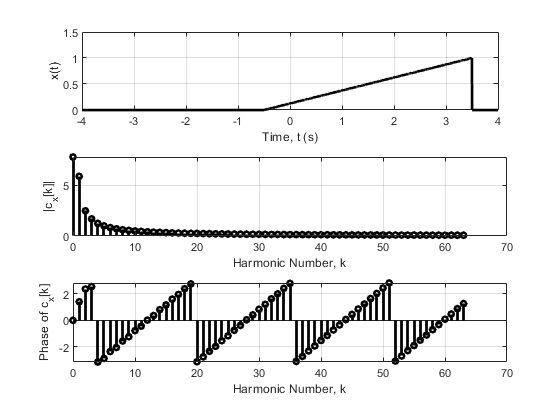

% Programe para aproximar, usando el DFT, el CTFS	de un 
% Señal periódica descrita durante un período por
% x(t) = sqrt(1-t^2), -1 < t < 1

narm=128;                                   % Número de armónicos tpmados para reconstruir la señal
T = 2 ;								        % Periodo fundamental
f=1/T;                                      % Frecuencia
fs=(1/T):1/T:(narm/T);                      % Normalizacion vector de Frecuencia
np=T*0.001;                                 % Espacio numerico definido en el periodo de la funcion (np=Numero de muestras en un periodo)
t=-(2*T):np:(2*T);                          % Limites del espacio numerico (eje de abscisas ¨tiempo¨)

% Calcule los valores de x(t) en los tiempos de muestreo
x = (t/4 + 1/8).*rectangularPulse(-1/2,7/2,t);
cx = fft(x)/narm;  % Muestras de DFT
k = [0:narm/2-1];							% Vector de números armónicos

% Graficas de resultados
subplot(3,1,1) ;
p = plot(t,x,'k'); set(p,'LineWidth',2); grid on ; axis('equal'); axis([0,4,0,1.5]),xlim([-2*T 2*T]) ;
xlabel('Time, t (s)') ; ylabel('x(t)') ; 
subplot(3,1,2) ;
p = stem(k,abs(cx(1:narm/2)),'k') ; set(p,'LineWidth',2,'MarkerSize',4) ; grid on ;
xlabel('Harmonic Number, k') ; ylabel('|c_x[k]|') ;
subplot(3,1,3) ;
p = stem(k,angle(cx(1:narm/2)),'k') ; set(p,'LineWidth',2,'MarkerSize', 4) ; grid on ;
xlabel('Harmonic Number, k') ; ylabel('Phase of c_x[k]') ;